
% Set the length of the SSH chain (2N)
N = 50;  % Chain length is 2N
delta = 0.9

delta = 0.9000

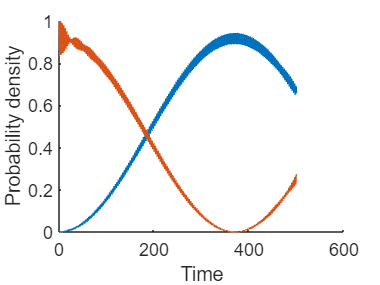

t1 = 1 - delta;  % Intracell coupling
t2 = 1 + delta;  % Intercell coupling
gamma = 0.4;  % Coupling strength between the qubits and the SSH chain

% Create the Hamiltonian matrix
H = zeros(2*N + 2);  % Include additional states for the qubits
for i = 1:2*N-1
    if mod(i,2) == 1
        H(i,i+1) = t1;
        H(i+1,i) = t1;
    else
        H(i,i+1) = t2;
        H(i+1,i) = t2;
    end
end

% Coupling the left qubit to the left end of the SSH chain
H(N + 3, 2*N+1) = gamma;
H(2*N+1, N + 3) = gamma;

% Coupling the right qubit to the right end of the SSH chain
H(N, 2*N+2) = gamma;
H(2*N+2, N) = gamma;

% Initialize the system with the left qubit in the excited state and right qubit in the ground state
psi0 = zeros(2*N + 2, 1);
psi0(end-1) = 0;  % The left qubit is in the excited state
psi0(end) = 1;    % The right qubit is in the ground state

% Ideal entangled state
phi_ideal = zeros(2*N + 2, 1);
phi_ideal(end-1) = 1 / sqrt(2);
phi_ideal(end) = j / sqrt(2);

% Time evolution parameters
t_max = 500;  % Maximum time
dt = 0.05;  % Time step
time_steps = t_max / dt;
psi_t = psi0;
prob_density = zeros(2*N+2, time_steps);
fidelity = zeros(1, time_steps);

% Time evolution
for t = 1:time_steps
    psi_t = expm(-1i * H * dt) * psi_t;  % Time evolution operator
    prob_density(:, t) = abs(psi_t).^2;  % Probability density at each site
    % Calculate the fidelity with the ideal entangled state
    fidelity(t) = abs(phi_ideal' * psi_t)^2;
end


% Plot the time evolution of the qubits' probability density
figure;
hold on
plot((1:time_steps) * dt, prob_density(end-1, :));
plot((1:time_steps) * dt, prob_density(end, :));
xlabel('Time');
ylabel('Probability density');
hold off

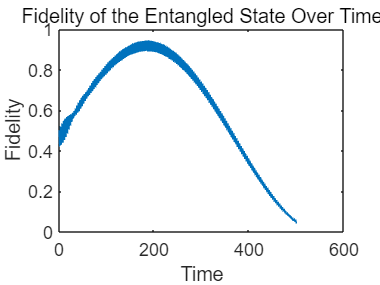


% Plot the fidelity over time
figure;
plot((1:time_steps) * dt, fidelity);
xlabel('Time');
ylabel('Fidelity');
title('Fidelity of the Entangled State Over Time');